%Definizione delle caratteristiche del robot
clc 
clear all

% Robot characteristcs [m]
l1 = 0.5; l1_w = 0.1; l1_h = 0.03; % link1
l2 = 1;   l2_w = 0.1; l2_h = 0.03;% link2
h = 0.8; % height
l0 = 0.5; % shoulder difference

L=[h; l0; l1; l2]';

g1=l1/2;  g2=l1/2; % link1
g3=l2/2;  g4=l2/2; %link2

G=[g1; g2; g3; g4]';

m1 = 10; % link1
m2 = 3; %link2
m_gripper = 1; % gripper
Jg1=0.03; % MoI link1
Jg2=0.03; % MoI link2
Jg = 0.01; % MoI gripper

M = diag([(m_gripper/2),(m_gripper/2),m2,m2,(Jg+Jg2),m1,m1,Jg1,m1,m1]);

S0=[-0.5;1;0.2];  % gripper first position
S1=[1;0.5;0.7];     % gripper final position

dS = S1 - S0;
T = 5;
n = 100;
dT = T/(n-1);



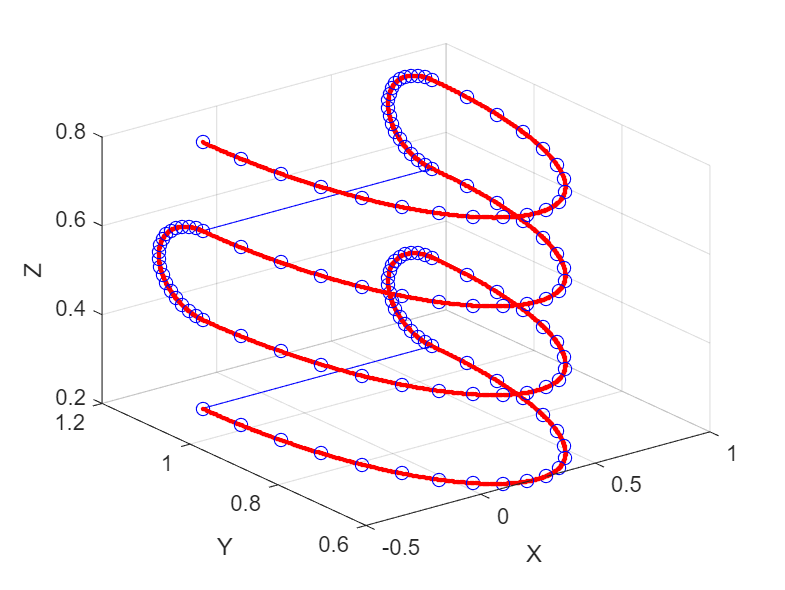

close all
figure(1)

R = 0.5; dH = 0.1;

x=l0/2;      
y=1.1;
r=R;
theta = linspace(-pi, 0, 500);
px = r * cos(theta) + x;
py = r * sin(theta) + y;
pz = linspace(h,h,500);
pt = interparc(20,px,py,pz,'spline');

px_new=linspace(px(end),px(end),500);
y=pz(end)-dH;
z=py(end);
r=dH;
theta = linspace(0, pi, 500);
pz_new=r*cos(theta)+y;
py_new=r*sin(theta)+z;
pt = [pt; interparc(20,px_new,py_new,pz_new,'spline')];
px = [px px_new]; py=[py py_new];   pz=[pz pz_new];

x=l0/2;      
y=1.1;
r=R;
theta = linspace(-pi, 0, 500);
px_new = r*cos(theta)+x;
py_new = r*sin(theta)+y;
pz_new = linspace(pz(end),pz(end),500);
pt = [pt; interparc(20,px_new,py_new,pz_new,'spline')];
px = [px px_new]; py=[py py_new];   pz=[pz pz_new];

px_new=linspace(px(end)-1.,px(end)-1,500);
y=pz(end)-dH;
z=py(end);
r=dH;
theta = linspace(0, pi, 500);
pz_new=r*cos(theta)+y;
py_new=r*sin(theta)+z;
pt = [pt; interparc(20,px_new,py_new,pz_new,'spline')];
px = [px px_new]; py=[py py_new];   pz=[pz pz_new];


x=l0/2;      
y=1.1;
r=R;
theta = linspace(-pi, 0, 500);
px_new = r*cos(theta)+x;
py_new = r*sin(theta)+y;
pz_new = linspace(pz(end),pz(end),500);
pt = [pt; interparc(20,px_new,py_new,pz_new,'spline')];
px = [px px_new]; py=[py py_new];   pz=[pz pz_new];

px_new=linspace(px(end),px(end),500);
y=pz(end)-dH;
z=py(end);
r=dH;
theta = linspace(0, pi, 500);
pz_new=r*cos(theta)+y;
py_new=r*sin(theta)+z;
pt = [pt; interparc(20,px_new,py_new,pz_new,'spline')];
px = [px px_new]; py=[py py_new];   pz=[pz pz_new];

x=l0/2;      
y=1.1;
r=R;
theta = linspace(-pi, 0, 500);
px_new = r*cos(theta)+x;
py_new = r*sin(theta)+y;
pz_new = linspace(pz(end),pz(end),500);
pt = [pt; interparc(20,px_new,py_new,pz_new,'spline')];
px = [px px_new]; py=[py py_new];   pz=[pz pz_new];

figure
plot3(px,py,pz,'.r')
hold on
plot3(pt(:,1),pt(:,2),pt(:,3),'b-o')
grid on
xlabel X
ylabel Y
zlabel Z